# MSD Assignment Part 2

#### Script prepared by: Aditya Natu, PhD Candidate, Mechatronics System Design

clear; clc; close all;

This script is developed to showcase control design process and code functions for a given plant as an **example**. Students are expected to **modify** and **adapt** the script for the system provided in the assignment.

# Feedback Control Design

## Load Plant

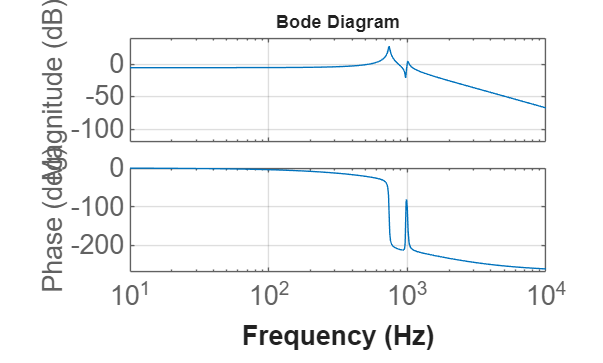

load MSD2024_P2_Plant.mat  % Load plant transfer function
shapeit_data_no_notch = load('C_no_notch.mat', 'shapeit_data'); % Load Controller from ShapeIt (No notch)
shapeit_data_notch = load('C_notch.mat', 'shapeit_data'); % Load Controller from ShapeIt
shapeit_final = load("A.1_C_final.mat", "shapeit_data"); % Load Final Controller from ShapeIt
s = tf('s'); 

% Define bode options
opts = bodeoptions('cstprefs');
opts.FreqUnits = 'Hz';
opts.XLim= [10 10000];
opts.PhaseVisible = 'on';
opts.PhaseWrapping = 'off';
opts.Grid = 'on';
opts.XLabel.String = 'Frequency';
opts.XLabel.FontSize = 16;
opts.XLabel.FontWeight = 'bold';
opts.YLabel.String = {'Magnitude','Phase'};
opts.YLabel.FontSize = 16;
opts.YLabel.FontWeight = 'bold';
opts.TickLabel.FontSize = 16;

figure(1);clf(1);
bode(G,opts)


display(G)


G =
 
                        7.914e25 s^2 + 4.833e27 s + 2.952e33
  ---------------------------------------------------------------------------------
  7.559e14 s^5 + 6.713e18 s^4 + 4.797e22 s^3 + 4.075e26 s^2 + 6.926e29 s + 5.638e33
 
Continuous-time transfer function.
Model Properties


## Design PID-Type Controller

% Simple PID based on rule of thumb
% General Form: C = (kp/a)*(1 + wi/s)*(s/wd + 1)/(s/wt + 1);

% wc = 536*2*pi; % Choose appropriate wc
% a = 7; % Differentiator band
% kp = (1/a) * (1 / abs(freqresp(G, wc)));
% wi = wc/10;
% wd = wc/a; 
% wt = wc*a;
% 
% 
% % Notch filter parameters
% wnf = 736 * 2 * pi; % Notch resonance frequency
% Q1 = 0.05; % Notch quality factor numerator
% Q2 = 0.9; % Notch quality factor denominator
% N = ((s/wnf)^2 + (s/(Q1*wnf)) + 1) / ((s/wnf)^2 + (s/(Q2*wnf)) + 1);
% 
% C = (kp/a)*(1 + wi/s)^2*((s/wd + 1) / (s/wt + 1)) * N

C = tf(shapeit_final.shapeit_data.C_tf.Numerator, shapeit_final.shapeit_data.C_tf.Denominator)


C =
 
  0.01098 s^4 + 16.38 s^3 + 2.412e05 s^2 + 3.075e08 s + 8.062e10
  --------------------------------------------------------------
       0.001989 s^4 + 56.2 s^3 + 7.029e04 s^2 + 2.139e07 s
 
Continuous-time transfer function.
Model Properties


### Visualize Frequency Response

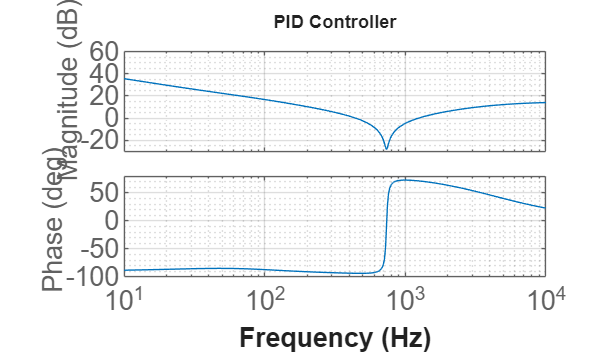

figure(1);clf(1);
bode(C, opts);
title('PID Controller')
grid on; grid minor;

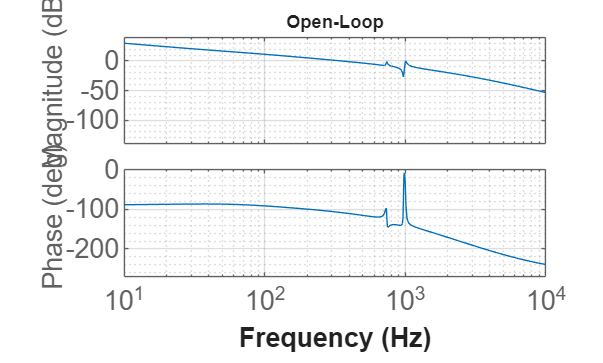


% Open-Loop
L = G*C; 
figure(2);clf(2);
bode(L,opts);
title('Open-Loop')
grid on; grid minor;

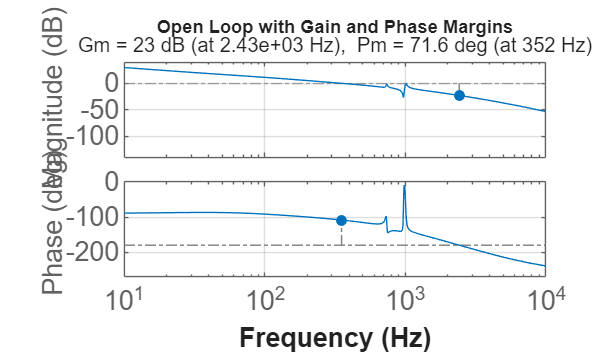


figure(3); margin(L, opts);
title('Open Loop with Gain and Phase Margins')% Evaluate Gain and Phase Margins

## Closed-Loop Plots

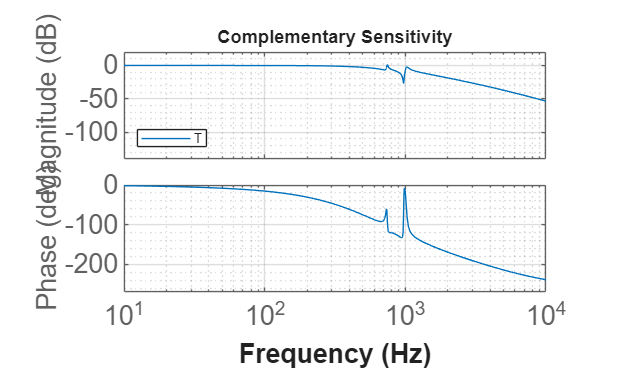

T = L/(1+L); % Complementary Sensitivity
S = 1/(1+L); % Sensitivity

figure(4);clf(4);
bode(T,opts); title('Complementary Sensitivity')
legend(Location='southwest')
grid on; grid minor;

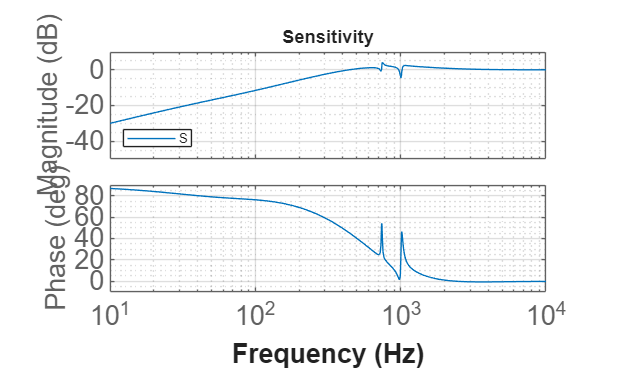


figure(5); clf(5);
bode(S, opts);title('Sensitivity')
legend(Location='southwest')
grid on; grid minor; 

## Connect Function for Closed-Loop Analysis

% Define input-output variables
G.u='u'; G.y='x';
C.u='e'; C.y='v';

S1 = sumblk("e = r - y");
S2 = sumblk("u = d + v");
S3 = sumblk("y = x + n");

Tconnect = connect(G,C,S1,S2,S3,"r","y");

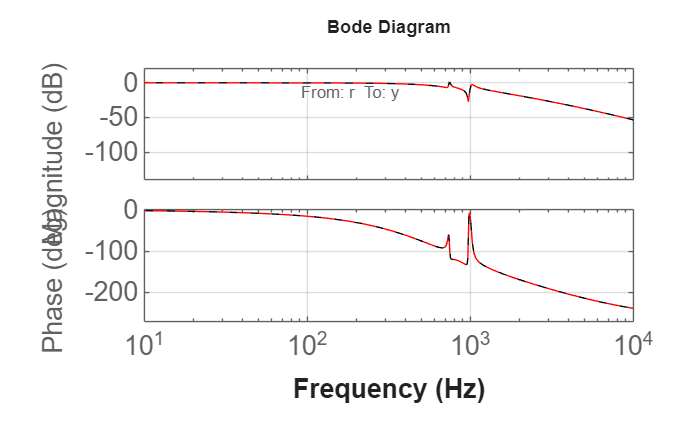


figure(1);clf(1);
bode(T,'k',Tconnect,'r--',opts)

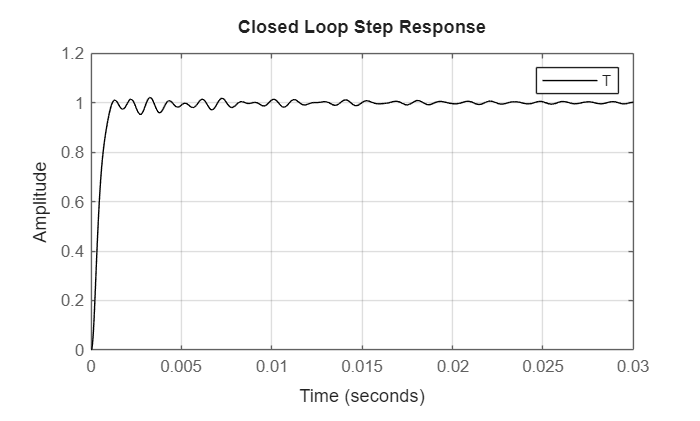


%% Stability Check
figure(2);clf(2);
step(T, 'k'); grid on;
legend
title('Closed Loop Step Response')


Control_info = stepinfo(Tconnect)

Control_info = struct with fields:
         RiseTime: 7.1017e-04
    TransientTime: 0.0068
     SettlingTime: 0.0068
      SettlingMin: 0.9018
      SettlingMax: 1.0211
        Overshoot: 2.1110
       Undershoot: 0
             Peak: 1.0211
         PeakTime: 0.0033


## Feedforward Controller 

% Feedforward controller
F = inv(G);

% Add a 4th order LP filter
wc = 2 * pi * 1000; % Cut-off frequency
H = 1 / (1 + s/wc)^4; % Low pass filter
F_LP = F * H


F_LP =
 
  From input to output "u":
          1.178e30 s^5 + 1.046e34 s^4 + 7.476e37 s^3 + 6.35e41 s^2 + 1.079e45 s + 8.787e48
  ------------------------------------------------------------------------------------------------
  7.914e25 s^6 + 1.994e30 s^5 + 2.182e34 s^4 + 1.539e38 s^3 + 8.274e41 s^2 + 2.936e45 s + 4.601e48
 
Continuous-time transfer function.


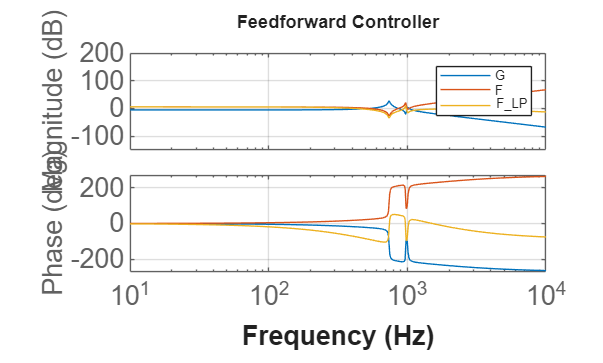


figure(1);clf(1);
bode(G,F,F_LP, opts)
legend
title('Feedforward Controller')


% Is it proper (/strictly) proper? Tame it to make it proper!
isproper(F_LP)

ans = logical
   1


## **Closed Loop: Feedback + Feedforward**

% Define input and output variables
G.u='u'; G.y='x';
C.u='e'; C.y='v';
F_LP.u='r';F_LP.y='f';

S1 = sumblk("e = r - y");
S2 = sumblk("w = f + v");
S3 = sumblk("u = d + w");
S4 = sumblk("y = x + n");

Tconnect2 = connect(G,C,F_LP,S1,S2,S3,S4,"r","y");

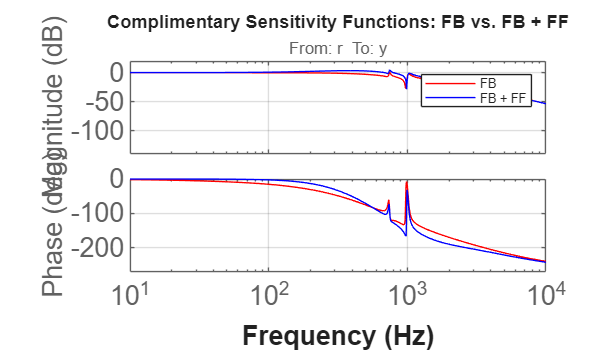


figure(2);clf(2);
bode(Tconnect,'r', Tconnect2, 'b', opts)
title('Complimentary Sensitivity Functions: FB vs. FB + FF')
legend('FB', 'FB + FF')

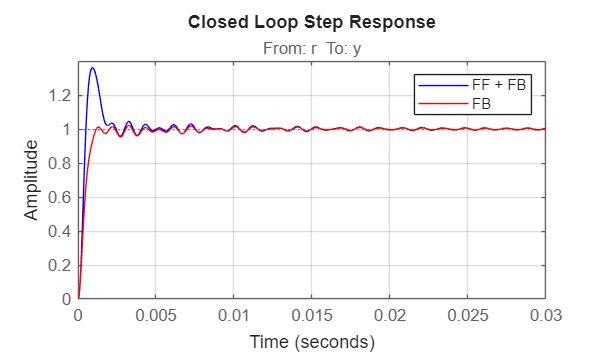


%% Stability Check
figure(3);clf(3);
step(Tconnect2, 'b', Tconnect, 'r'); grid on;
legend('FF + FB', 'FB')
title('Closed Loop Step Response')


FF_info = stepinfo(Tconnect2)

FF_info = struct with fields:
         RiseTime: 3.2333e-04
    TransientTime: 0.0107
     SettlingTime: 0.0107
      SettlingMin: 0.9012
      SettlingMax: 1.3606
        Overshoot: 36.0622
       Undershoot: 0
             Peak: 1.3606
         PeakTime: 9.3483e-04


Control_info

Control_info = struct with fields:
         RiseTime: 7.1017e-04
    TransientTime: 0.0068
     SettlingTime: 0.0068
      SettlingMin: 0.9018
      SettlingMax: 1.0211
        Overshoot: 2.1110
       Undershoot: 0
             Peak: 1.0211
         PeakTime: 0.0033


# Closed - Loop System Identification

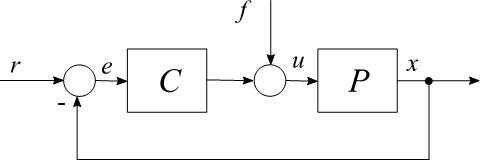

Given Signals: ***f, u, x, e*** (Signal names according to presented architecture, this can vary!)

***x*** includes sensor noise!

## Load Signal Data

% %clear all; close all; clc; 
% 
% load('TimeDataMIPsetup.mat')
% 
% Fs          = TimeData_10Hz.Fs; % [Hz] sampling frequency
% Ts          = 1/Fs; % [s] sample time
% frq         = TimeData_10Hz.frq; % [Hz] frequency vector in excitation signal
% t           = TimeData_10Hz.t; % [s] time vector
% n_aver      = TimeData_10Hz.n_aver; % [-] number of averages in multi sine signal 
% Data        = TimeData_10Hz.Data; % [N,N,m,m] Data
% 
% % Plot Signals
% figure(1);clf(1);
% plot(TimeData_10Hz.t(:),TimeData_10Hz.Data(:,1)) % f 10Hz
% hold on
% plot(TimeData_10Hz.t(:),TimeData_10Hz.Data(:,2)) % u 10Hz
% hold on
% plot(TimeData_10Hz.t(:),TimeData_10Hz.Data(:,3)) % x 10Hz
% hold on
% plot(TimeData_10Hz.t(:),TimeData_10Hz.Data(:,4)) % e 10Hz
% grid on
% xlabel('Time (s)')
% ylabel('Amplitude')
% legend('f_{10Hz}','u_{10Hz}','x_{10Hz}','e_{10Hz}')

## Transfer Function Estimate

% ft10 = TimeData_10Hz.frq; % Frequency Vector
% 
% % Get input-output signal pairs
% inpt = TimeData_10Hz.Data(:,1);
% outpt = TimeData_10Hz.Data(:,2); %u/f
% 
% inpt2 = TimeData_10Hz.Data(:,1);
% outpt2 = TimeData_10Hz.Data(:,3); %x/f
% 
% inpt3 = TimeData_10Hz.Data(:,1);
% outpt3= TimeData_10Hz.Data(:,4); %e/f
% 
% % Use tfestimate() function 
% 
% wind = []; % Apply appropriate windowing and choose window length
% % Similarly, for overlap, if necessary
% % Evaluate coherence!
% 
% [T,f] = tfestimate(inpt,outpt,wind,[],ft10,Fs); %u/f
% [C,f] = mscohere(inpt,outpt,wind,[],ft10,Fs);
% 
% [T2,f2] = tfestimate(inpt2,outpt2,wind,[],ft10,Fs); %x/f
% [C2,f2] = mscohere(inpt2,outpt2,wind,[],ft10,Fs);
% 
% [T3,f3] = tfestimate(inpt3,outpt3,wind,[],ft10,Fs); %e/f
% [C3,f3] = mscohere(inpt3,outpt3,wind,[],ft10,Fs);
% 
% 
% % Plot Closed-Loop Identified Sensitivities
% figure(1);clf(1); 
% subplot(2,1,1);
% semilogx(f,mag2db(abs(T))); hold on;
% %semilogx(f,mag2db(abs(T2))); hold on;
% semilogx(f,mag2db(abs(T3))); hold on;
% xlabel('Frequency (Hz)')
% ylabel('Magnitude (dB)')
% grid on
% title('Estimated Closed-Loop Sensitivities')
% subplot(2,1,2);
% semilogx(f,rad2deg(angle(T))); hold on;
% %semilogx(f,rad2deg(angle(T2))); hold on;
% semilogx(f,rad2deg(angle(T3))); hold on;
% xlabel('Frequency (Hz)')
% ylabel('Phase (deg)')
% legend('u/f','e/f')
% grid on

## Obtain Plant Model from Closed-Loop Senstivities

% Pestimate = -T3./T; % -(e/f)/(u/f)
% 
% % Plot Plant
% figure(1);clf(1);
% subplot(2,1,1);semilogx(f,mag2db(abs(Pestimate)));
% xlabel('Frequency (Hz)')
% ylabel('Magnitude (dB)')
% grid on
% title('Estimated Plant Model')
% subplot(2,1,2);semilogx(f,rad2deg(angle(Pestimate)));
% xlabel('Frequency (Hz)')
% ylabel('Phase (deg)')
% grid on
% 